# Investigation of the friction velocity

The friction velocity retrieved with the double and triple rotation as well as the planar fit algorithm is compared to the target one.

The friction velocity is here calculated as:


$$u_* = \left(\overline{u^{\prime}w^{\prime}}^2 + \overline{v^{\prime}w^{\prime}}^2\right)^{1/4}$$


## Generate tilted wind velocity records

clearvars;close all;clc;
% load simlated wind velocities
load('data.mat','u','v','w','t')
[M,N]=size(u);

yaw  = 30; % yaw angle (horizontal plane, between u and v)
elev = 3; % elevation angle (vertical plane, between w and u)
incl = 2; % inclination angle (vertical plane, between w and v)

R1 = [cosd(yaw),-sind(yaw),0;sind(yaw),cosd(yaw),0;0,0,1]; % matrix rotation around axis z
R2 = [cosd(elev),0,-sind(elev);0,1,0;sind(elev),0,cosd(elev)]; % matrix rotation around axis zy
R3 = [1,0,0; 0,cosd(incl),-sind(incl);0,sind(incl),cosd(incl)]; % matrix rotation around axis x


A = R1*R2*R3;  % 3D rotation matrix

% Construction of tilted velocity component
u_tilted = zeros(size(u));
v_tilted = zeros(size(u));
w_tilted = zeros(size(u));
for ii=1:M,
    dummy = A\[u(ii,:);v(ii,:);w(ii,:)];
    u_tilted(ii,:) = dummy(1,:);
    v_tilted(ii,:) = dummy(2,:);
    w_tilted(ii,:) = dummy(3,:);
end

##  Double rotation

tic
[u3,v3,w3] = tiltCorrection(u_tilted,v_tilted,w_tilted,'method','rot2');
toc

Elapsed time is 0.053081 seconds.



meanIncidence = 180/pi.*nanmean(atan2(nanmean(w3,2),nanmean(u3,2)));
fprintf(['Mean incidence angle is ',num2str(meanIncidence),' \n']);

Mean incidence angle is -1.8338e-15 


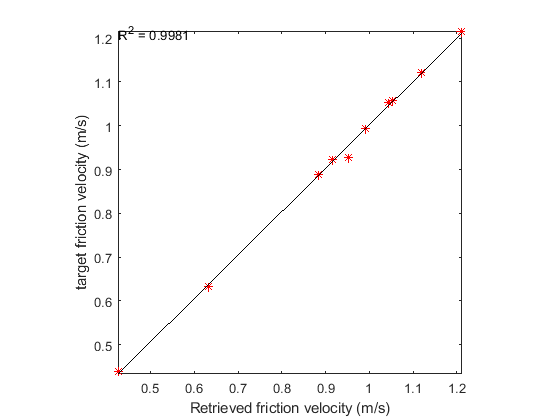


%  Verification of friction velocity
u_star0 = zeros(1,M);
u_star3 = zeros(1,M);
covVW = zeros(1,M);
covUW = zeros(1,M);
for ii = 1:M,
    [u_star0(ii)] = frictionVelocity(u(ii,:),v(ii,:),w(ii,:));
    [u_star3(ii)] = frictionVelocity(u3(ii,:),v3(ii,:),w3(ii,:));
    covVW(ii) = nanmean(detrend(v3(ii,:)).*detrend(w3(ii,:)));
    covUW(ii) = nanmean(detrend(u3(ii,:)).*detrend(w3(ii,:)));
end

fig1 = figure;
plot(u_star0,u_star3,'r*');
hold on;box on;
p = polyfit(u_star0,u_star3,1);
x = linspace(nanmin(u_star0(:)),nanmax(u_star0(:)),2);
y = polyval(p,x);
plot(x,y,'k')
[r p] = corr(u_star0',u_star3');
text(quantile(u_star0(:),0.0075),quantile(u_star0(:),0.9925),['R^2 = ' num2str(r.^2,4)]) ; % Add the value of r to the plot.
daspect([1 1 1])
axis equal
axis tight
ylabel('target friction velocity (m/s)')
xlabel('Retrieved friction velocity (m/s)')
set(gcf,'color','w')

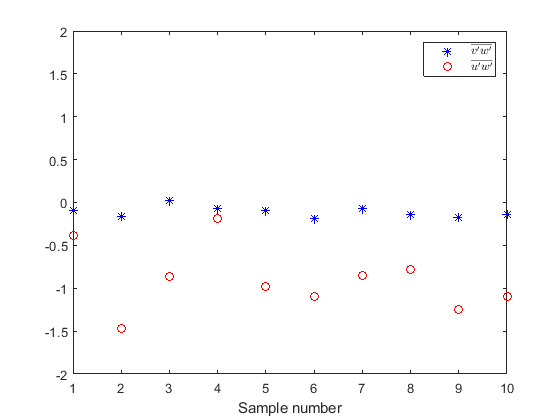



figure
plot(1:M,covVW,'b*',1:M,covUW,'ro')
leg = legend('$\overline{v^{\prime}w^{\prime}}$','$\overline{u^{\prime}w^{\prime}}$');
set(leg,'interpreter','latex');
xlabel('Sample number')
ylim([-2,2])

## Triple rotation

tic
[u3,v3,w3] = tiltCorrection(u_tilted,v_tilted,w_tilted,'method','rot3');
toc

Elapsed time is 0.038736 seconds.


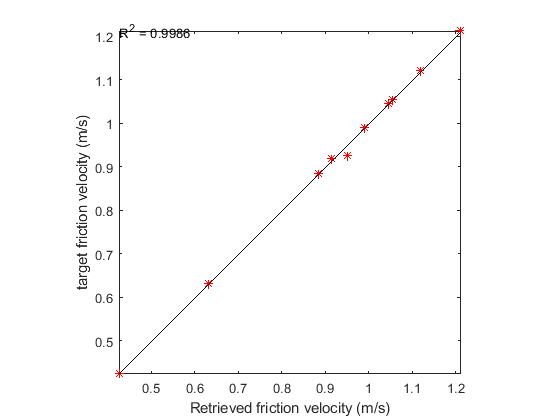


%  Verification of friction velocity
u_star0 = zeros(1,M);
u_star3 = zeros(1,M);
covVW = zeros(1,M);
covUW = zeros(1,M);
for ii = 1:M,
    [u_star0(ii)] = frictionVelocity(u(ii,:),v(ii,:),w(ii,:));
    [u_star3(ii)] = frictionVelocity(u3(ii,:),v3(ii,:),w3(ii,:));
    
    covVW(ii) = nanmean(detrend(v3(ii,:)).*detrend(w3(ii,:)));
    covUW(ii) = nanmean(detrend(u3(ii,:)).*detrend(w3(ii,:)));
end


clf;close all;
fig3 = figure;
plot(u_star0,u_star3,'r*');
hold on;box on;
p = polyfit(u_star0,u_star3,1);
x = linspace(nanmin(u_star0(:)),nanmax(u_star0(:)),2);
y = polyval(p,x);
plot(x,y,'k')
[r p] = corr(u_star0',u_star3');
text(quantile(u_star0(:),0.0075),quantile(u_star0(:),0.9925),['R^2 = ' num2str(r.^2,4)]) ; % Add the value of r to the plot.
daspect([1 1 1])
axis equal
axis tight
ylabel('target friction velocity (m/s)')
xlabel('Retrieved friction velocity (m/s)')
set(gcf,'color','w')

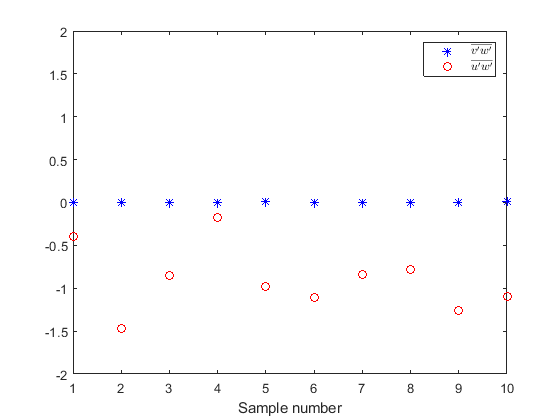


figure
plot(1:M,covVW,'b*',1:M,covUW,'ro')
leg = legend('$\overline{v^{\prime}w^{\prime}}$','$\overline{u^{\prime}w^{\prime}}$');
set(leg,'interpreter','latex');
xlabel('Sample number')
ylim([-2,2])

## Planar fit

tic
[u3,v3,w3] = tiltCorrection(u_tilted,v_tilted,w_tilted,'method','PF');

   0.00000   -0.05206   -0.03427 


toc

Elapsed time is 0.050188 seconds.


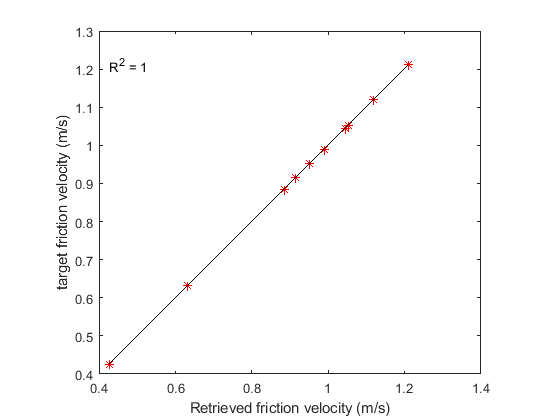


%  Verification of friction velocity
u_star0 = zeros(1,M);
u_star3 = zeros(1,M);
covVW = zeros(1,M);
covUW = zeros(1,M);
for ii = 1:M,
    [u_star0(ii)] = frictionVelocity(u(ii,:),v(ii,:),w(ii,:));
    [u_star3(ii)] = frictionVelocity(u3(ii,:),v3(ii,:),w3(ii,:));
    
    covVW(ii) = nanmean(detrend(v3(ii,:)).*detrend(w3(ii,:)));
    covUW(ii) = nanmean(detrend(u3(ii,:)).*detrend(w3(ii,:)));
end

clf;close all;
fig5 = figure;
plot(u_star0,u_star3,'r*');
% xlim([0.3,0.45])
% ylim([0.3,0.45])
daspect([1 1 1])
hold on;box on;
p = polyfit(u_star0,u_star3,1);
x = linspace(nanmin(u_star0(:)),nanmax(u_star0(:)),2);
y = polyval(p,x);
plot(x,y,'k')
[r p] = corr(u_star0',u_star3');
text(quantile(u_star0(:),0.0075),quantile(u_star0(:),0.9925),['R^2 = ' num2str(r.^2,4)]) ; % Add the value of r to the plot.

ylabel('target friction velocity (m/s)')
xlabel('Retrieved friction velocity (m/s)')
set(gcf,'color','w')

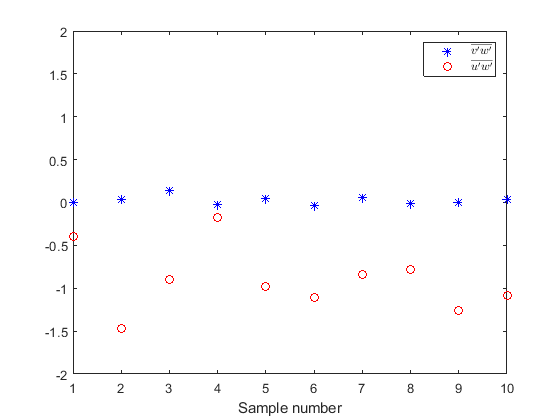



figure
plot(1:M,covVW,'b*',1:M,covUW,'ro')
leg = legend('$\overline{v^{\prime}w^{\prime}}$','$\overline{u^{\prime}w^{\prime}}$');
set(leg,'interpreter','latex');
xlabel('Sample number')
ylim([-2,2])